- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

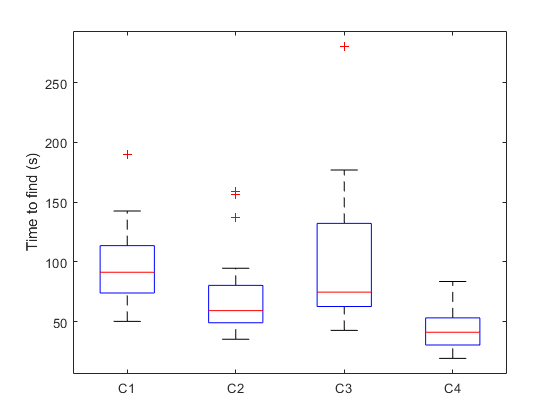

% time to find
% hyp: time to find will depend on prior knowledge. 
timeArray = csvread('stats data/timeData.csv');
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find (s)')

% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                        SumSq    DF    MeanSq      F         pValue      pValueGG      pValueHF     pValueLB 
                        _____    __    ______    ______    __________    _________    __________    _________

    (Intercept):cond    47697     3     15899    14.022    3.1085e-07    8.818e-06    3.4188e-06    0.0010583
    Error(cond)         78235    69    1133.8                                                                


if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
end

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         25.873      7.5925      0.014476     3.9595     47.787
      1         3        -1.5769      11.759             1    -35.517     32.363
      1         4         53.002      7.7561    3.4359e-06     30.616     75.388
      2         1        -25.873      7.5925      0.014476    -47.787    -3.9595
      2         3         -27.45      11.796       0.17473    -61.496     6.5956
      2         4         27.129       6.607     0.0025929     8.0592     46.198
      3         1         1.5769      11.759             1    -32.363     35.517
      3   

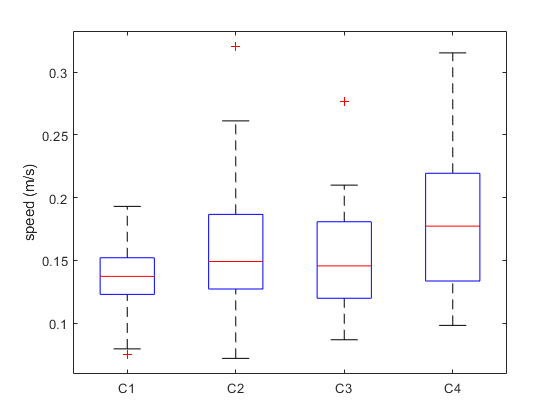



% speed
% hyp: speed will depend on prior knowledge.
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
EKFSpdData = EKFSpdData((EKFSpdData(:,5) ~= 0), :);
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('speed (m/s)')

rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq      DF     MeanSq        F         pValue      pValueGG     pValueHF    pValueLB
                        ________    __    _________    ______    __________    _________    ________    ________

    (Intercept):cond    0.027189     3    0.0090629    6.3454    0.00062543    0.0011043    0.000669    0.017758
    Error(cond)          0.11997    84    0.0014283                                                             


if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
end

res_EKFSpd = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper  
    ______    ______    __________    _________    __________    __________    _________

      1         2       -0.022433     0.0083034      0.069491     -0.046006    0.0011395
      1         3       -0.015456     0.0091217       0.60764     -0.041352      0.01044
      1         4       -0.042606     0.0094314    0.00062161     -0.069381    -0.015831
      2         1        0.022433     0.0083034      0.069491    -0.0011395     0.046006
      2         3        0.006977       0.01145             1     -0.025529     0.039483
      2         4       -0.020173     0.0094968       0.25573     -0.047134    0.0067879
      3         1        

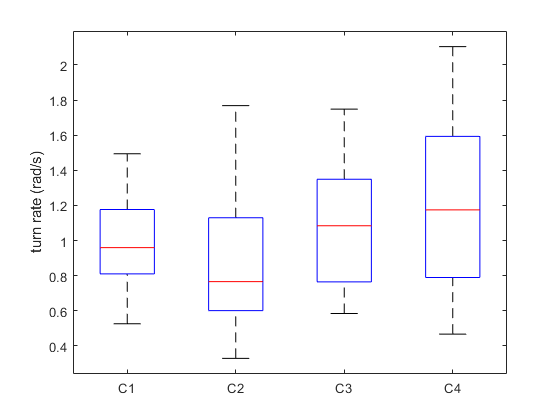



% turn rate
% hyp: turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
EKFOmegaArray = EKFOmegaArray((EKFOmegaArray(:,5) ~= 0), :);
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('turn rate (rad/s)')

rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                        SumSq     DF    MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    _______    ______    ________    ________    ________    ________

    (Intercept):cond    1.4447     3    0.48155    3.5578    0.017681    0.02438     0.020241    0.069678
    Error(cond)          11.37    84    0.13535                                                          


if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
end

res_EKFOmega = 12×7 table
    cond_1    cond_2    Difference     StdErr      pValue       Lower       Upper  
    ______    ______    __________    ________    ________    _________    ________

      1         2        0.087183     0.092487           1     -0.17538     0.34975
      1         3        -0.11274      0.06589     0.58872      -0.2998    0.074312
      1         4        -0.20759     0.092639      0.1989     -0.47058    0.055405
      2         1       -0.087183     0.092487           1     -0.34975     0.17538
      2         3        -0.19993      0.10107     0.34706     -0.48687    0.087017
      2         4        -0.29477      0.10902    0.069154     -0.60428    0.014739
      3         1         0.11274      0.06589     0.58872    -

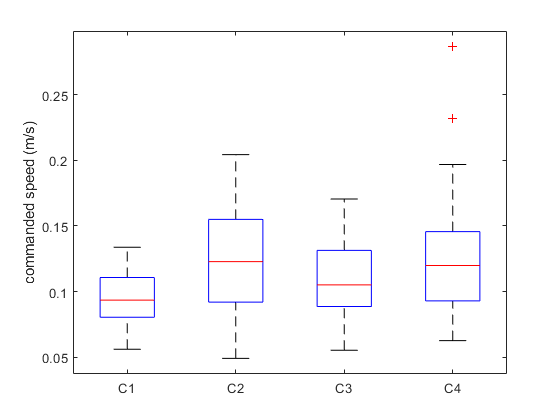


% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
comSpeedArray = comSpeedArray((comSpeedArray(:,5) ~= 0), :);
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('commanded speed (m/s)')

rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                         SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.020656     3     0.0068854    8.5502    5.0985e-05    0.00015406    7.9279e-05    0.0067722
    Error(cond)         0.067644    84    0.00080529                                                                 


if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
end

res_comSpeed = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper  
    ______    ______    __________    _________    __________    __________    _________

      1         2        -0.028955    0.0064117    0.00062418     -0.047157    -0.010753
      1         3        -0.013277    0.0054914       0.13423     -0.028867    0.0023125
      1         4        -0.033813     0.008039     0.0014474     -0.056635    -0.010991
      2         1         0.028955    0.0064117    0.00062418      0.010753     0.047157
      2         3         0.015678     0.007368       0.25377    -0.0052397     0.036595
      2         4       -0.0048581    0.0081339             1      -0.02795     0.018233
      3         1      

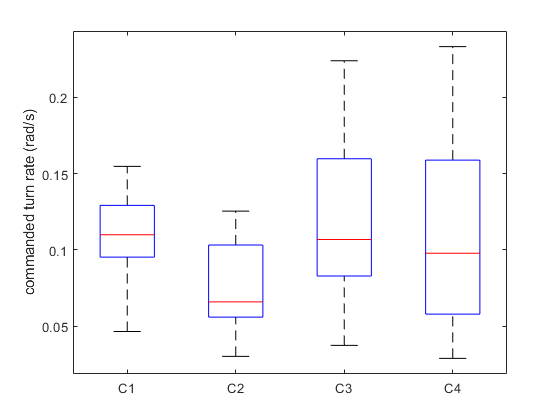



% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
comTurnRateArray = comTurnRateArray((comTurnRateArray(:,5) ~= 0), :);
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('commanded turn rate (rad/s)')

rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF     MeanSq        F        pValue       pValueGG      pValueHF     pValueLB
                        ________    __    _________    _____    __________    __________    __________    ________

    (Intercept):cond    0.028859     3    0.0096196    7.374    0.00019116    0.00091236    0.00060826    0.011208
    Error(cond)          0.10958    84    0.0013045                                                               


if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
end

res_comTurnRate = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower          Upper   
    ______    ______    __________    _________    __________    __________    ___________

      1         2         0.034673    0.0062224    3.4917e-05      0.017008       0.052338
      1         3       -0.0060331    0.0077197             1     -0.027949       0.015883
      1         4        0.0032304    0.0095149             1     -0.023782       0.030243
      2         1        -0.034673    0.0062224    3.4917e-05     -0.052338      -0.017008
      2         3        -0.040706    0.0088622    0.00050559     -0.065865      -0.015547
      2         4        -0.031443     0.011034      0.048734     -0.062769    -0.00011678
    


% Total distance traveled
TotalTimeInPlaceArray = csvread('stats data/TotalDistanceTravel.csv');
t_TotalDist = array2table(TotalTimeInPlaceArray',...
    'VariableNames',{'C1','C2','C3','C4'});
TotalDist_bp = boxplot(table2array(t_TotalDist(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average total distance traveled (m)')
rm_TotalDist=fitrm(t_TotalDist,'C1-C4~1', 'WithinDesign', within);
stats_TotalDist = ranova(rm_TotalDist)
if stats_TotalDist.pValue(1) < 0.05
    res_TotalDist=multcompare(rm_TotalDist, 'cond', 'ComparisonType','bonferroni')
end

% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray',...
    'VariableNames',{'C1','C2','C3','C4','C5'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time in place (s)')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)
if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
end


% stopping percentage (bearings)
% hyp: stopping percentage will depend on prior knowledge. 
% higher stopping percentage when map is not known



% NASA TLX
% all stats

% post trial


% we place target in a different location in 4b to see the change in behavior
% when the participant realizes that their prior knowledge is inaccurate
% we compared the actions between condition 3, when they did not have any knowledge
% of target location and condition 4b, when they again don't have knowledge about target location
% but thought they did
% 3 and 4b


% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 